# Lotka-Volterra system and quality of ode45

Lotka-Voltera system is defined as a system of nonlinear ordinary differential equations:


$$\dot x = x(\alpha - \beta y) \\
\dot y = y(-\gamma + \delta x)$$


Define the parameters;

alpha =3;
beta =1;
gamma = 3;
delta = 2;

Stationary points are $z_0^* =\left(0,0\right)$and $z_1^* =\left(\frac{\gamma }{\delta \;},\frac{\alpha \;}{\beta \;}\right)$.

z_st0 = [0; 0];
z_st1 = [gamma/delta; alpha/beta];

First integral of the system is $V\left(x,y\right)=\delta x+\beta y-\mathrm{log}\left(x^{\gamma \;} y^{\alpha } \right)$:

V = @(x, y) delta*x + beta*y - log(x.^gamma .* y.^alpha);

Define initial conditions for `ode45`. Assume automatic time-step selection.

z_0 = [1.2, 1.2];
T = 2.21;
tspan = [0, T];
V_0 = V(z_0(1), z_0(2));

Integrate the system:

[t, z] = ode45(@(t, z) lotka_volterra(t, z, [alpha, beta, gamma, delta]), tspan, z_0);

Plot the trajectory:

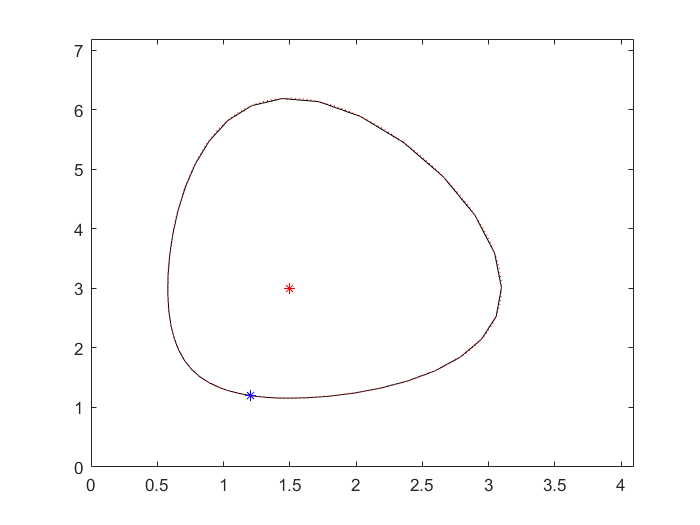

figure;
plot(z(:, 1), z(:, 2), '-k');
hold on;
plot(z_st1(1), z_st1(2), '*r')
plot(z_0(1), z_0(2), '*b')
fcontour(V, 'LevelList', V_0, 'LineColor', 'red', 'LineStyle', ':')
axis([0, max(z(:, 1)) + 1, 0, max(z(:, 2)) + 1]);
hold off;

Plot the difference between the actual first integral and the calculated first integral

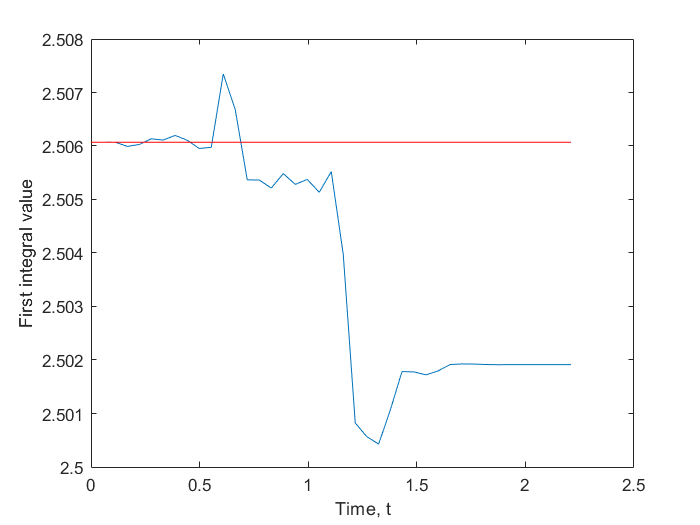

V_T = V(z(:, 1), z(:, 2));

figure;
plot(t, V_T);
line([0 t(end)], [V_0 V_0], 'Color', 'red')
xlabel('Time, t');
ylabel('First integral value');

Now consider a fixed time step $\tau \;$.

tau = logspace(-4, 0, 21).';

V_tau_max = zeros(size(tau));
V_tau_int = zeros(size(tau));
for k = 1 : length(tau)
    tspan = 0 : tau(k) : T;
    [t, z] = ode45(@(t, z) lotka_volterra(t, z, [alpha, beta, gamma, delta]), tspan, z_0);
    
    V_tau_max(k) = max(abs(V(z(:, 1), z(:, 2)) - V_0));
    V_tau_int(k) = sqrt(tau(k)*sum((V(z(:, 1), z(:, 2)) - V_0).^2));
end

Plot the resulting error in bilog scale

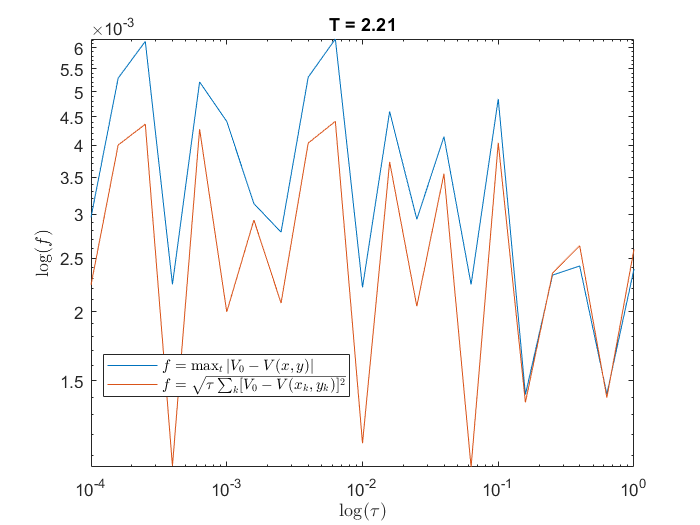

figure;
loglog(tau, V_tau_max);
hold on;
loglog(tau, V_tau_int);
hold off;
xlabel('$\log(\tau)$', 'Interpreter', 'latex');
ylabel('$\log(f)$', 'Interpreter', 'latex');
legend('$f = \max_t |V_0 - V(x, y)|$', '$f = \sqrt{\tau \sum_k [V_0 - V(x_k, y_k)]^2}$', 'Interpreter', 'latex', 'Location', 'best');
title(['T = ' num2str(T)])

Define function to solve Lotka-Volterra using `ode45`

function dz = lotka_volterra(~, z, par)
alpha = par(1);
beta = par(2);
gamma = par(3);
delta = par(4);

dz = zeros(2, 1);
dz(1) = z(1) * (alpha - beta*z(2));
dz(2) = z(2) * (-gamma + delta*z(1));
end